# Hard-coded matrices

clear; clc;

% Constants for BPSK
X = [-1, 1];  % BPSK constellation points
Q = [0.5; 0.5];  % Probability for each symbol (column vector)

% Quadrature parameters
N = 2;  % Number of quadrature points
M = length(X);  % Number of symbols
nodes = [-0.707107, 0.707107];  % Quadrature nodes (real)
weights = [0.886227, 0.886227];  % Quadrature weights

% SNR and Gaussian function
SNR = 1; 
G = @(z) (1/pi) * exp(-abs(z).^2);

% Z matrix with complex nodes
z_matrix = zeros(N, N);
for i = 1:length(nodes)
    for j = 1:length(nodes)
        z_matrix(i,j) = nodes(i) + 1i*nodes(j);
    end
end

% ------------ %

% Pi matrix
pi_block = weights(1)*weights(2);
pi_first_row = [pi_block, pi_block, pi_block, pi_block, 0, 0, 0, 0];
pi_second_row = [0, 0, 0, 0, pi_block, pi_block, pi_block, pi_block];
pi_matrix = [pi_first_row; pi_second_row];

% G matrix
g1_first_block = [G(z_matrix(1) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(1))), G(z_matrix(2) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(1))), G(z_matrix(3) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(1))), G(z_matrix(4) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(1)))];
g1_second_block = [G(z_matrix(1) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(2))), G(z_matrix(2) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(2))), G(z_matrix(3) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(2))), G(z_matrix(3) + (sqrt(SNR)*X(1)) - (sqrt(SNR)*X(2)))];
g1_third_block = [G(z_matrix(1) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(1))), G(z_matrix(2) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(1))), G(z_matrix(3) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(1))), G(z_matrix(3) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(1)))];
g1_fourth_block = [G(z_matrix(1) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(2))), G(z_matrix(2) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(2))), G(z_matrix(3) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(2))), G(z_matrix(3) + (sqrt(SNR)*X(2)) - (sqrt(SNR)*X(2)))];

g1_matrix = [g1_first_block, g1_second_block; g1_third_block, g1_fourth_block];

% Rho values
rho_values = linspace(0, 1, 1000);
Eo_rho = zeros(size(rho_values));

tic;

% Loop over rho values
for idx = 1:length(rho_values)
    rho = rho_values(idx);

    % Compute intermediate terms
    qg_rho = Q' * g1_matrix.^(1 / (1 + rho)); % 1x8 matrix
    qg_rho_t = qg_rho.^rho;  % Raise to power rho (1x8 matrix)
    pi_g_rho = pi_matrix .* g1_matrix.^(-rho / (1 + rho)); % Element-wise product (2x8 matrix)

    % Combine results into a single component
    component_second = Q' * (pi_g_rho * qg_rho_t');
    
    % Final calculation for E_0(rho)
    Eo_rho(idx) = -log2((1 / pi) * component_second);
end

elapsed_time = toc;
disp(['Elapsed time for computation: ', num2str(elapsed_time), 's']);

Elapsed time for computation: 0.013251s


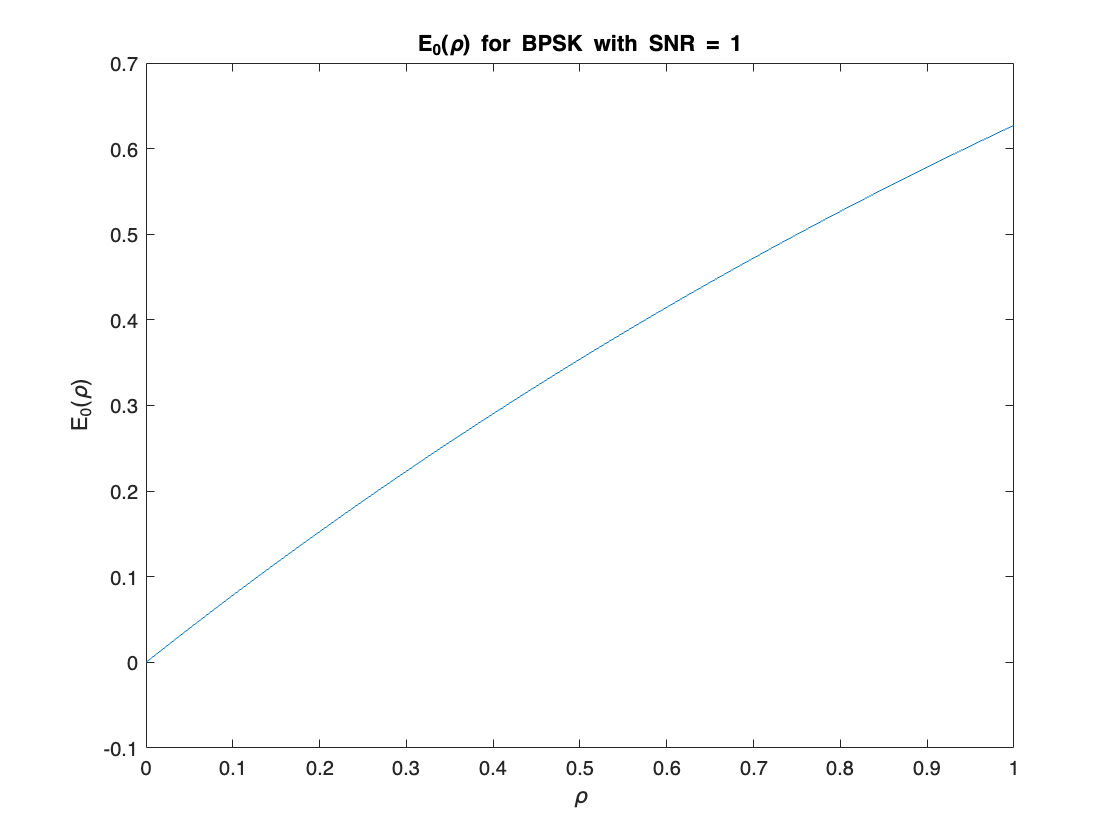

% Plot E0(rho)
figure;
plot(rho_values, Eo_rho);
xlabel('\rho');
ylabel('E_0(\rho)');
title(['E_0(\rho) for BPSK with SNR = ', num2str(SNR)]);

disp(Eo_rho)

   -0.0000    0.0008    0.0016    0.0024    0.0032    0.0040    0.0048    0.0056    0.0064    0.0072    0.0080    0.0088    0.0096    0.0104    0.0112    0.0120    0.0128    0.0136    0.0144    0.0152    0.0160    0.0168    0.0176    0.0184    0.0192    0.0200    0.0208    0.0216    0.0224    0.0232    0.0240    0.0248    0.0255    0.0263    0.0271    0.0279    0.0287    0.0295    0.0303    0.0311    0.0319    0.0327    0.0334    0.0342    0.0350    0.0358    0.0366    0.0374    0.0382    0.0389    0.0397    0.0405    0.0413    0.0421    0.0429    0.0436    0.0444    0.0452    0.0460    0.0468    0.0475    0.0483    0.0491    0.0499    0.0507    0.0514    0.0522    0.0530    0.0538    0.0545    0.0553    0.0561    0.0569    0.0576    0.0584    0.0592    0.0600    0.0607    0.0615    0.0623    0.0631    0.0638    0.0646    0.0654    0.0661    0.0669    0.0677    0.0685    0.0692    0.0700    0.0708    0.0715    0.0723    0.0731    0.0738    0.0746    0.0754    0.0761    0.0769    0.0776